(61/64)^148

ans = 8.2069e-04

chimp = getgenbank('NC_001643','SequenceOnly',true);
whos chimp

  Name       Size               Bytes  Class    Attributes

  chimp      1x16554            33108  char               



bases=basecount(chimp)

bases = struct with fields:
    A: 5154
    C: 5099
    G: 2133
    T: 4168


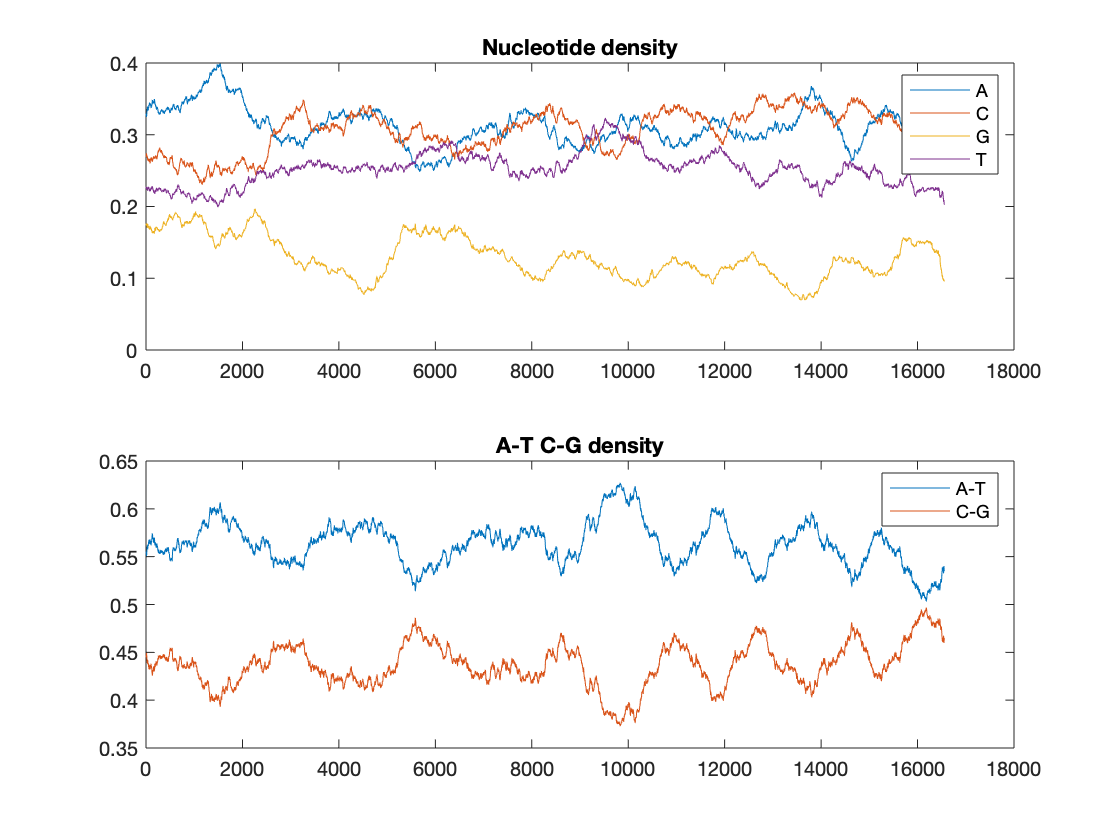

ntdensity(chimp)

length(chimp)

ans = 16554

codoncount(chimp)

AAA - 179     AAC - 165     AAG -  69     AAT - 145     
ACA - 127     ACC - 162     ACG -  35     ACT - 155     
AGA -  59     AGC - 101     AGG -  68     AGT -  54     
ATA - 131     ATC - 135     ATG -  52     ATT - 151     
CAA - 153     CAC - 139     CAG -  52     CAT - 142     
CCA - 148     CCC - 214     CCG -  46     CCT - 178     
CGA -  44     CGC -  45     CGG -  36     CGT -  34     
CTA - 187     CTC - 147     CTG -  59     CTT - 127     
GAA -  66     GAC -  61     GAG -  34     GAT -  44     
GCA -  73     GCC -  92     GCG -  13     GCT -  56     
GGA -  37     GGC -  42     GGG -  25     GGT -  34     
GTA -  43     GTC -  34     GTG -  13     GTT -  40     
TAA - 135     TAC - 141     TAG -  73     TAT - 117     
TCA - 100     TCC - 105     TCG -  29     TCT -  85     
TGA -  65     TGC -  45     TGG -  37     TGT -  32     
TTA - 104     TTC - 102     TTG -  27     TTT -  75     



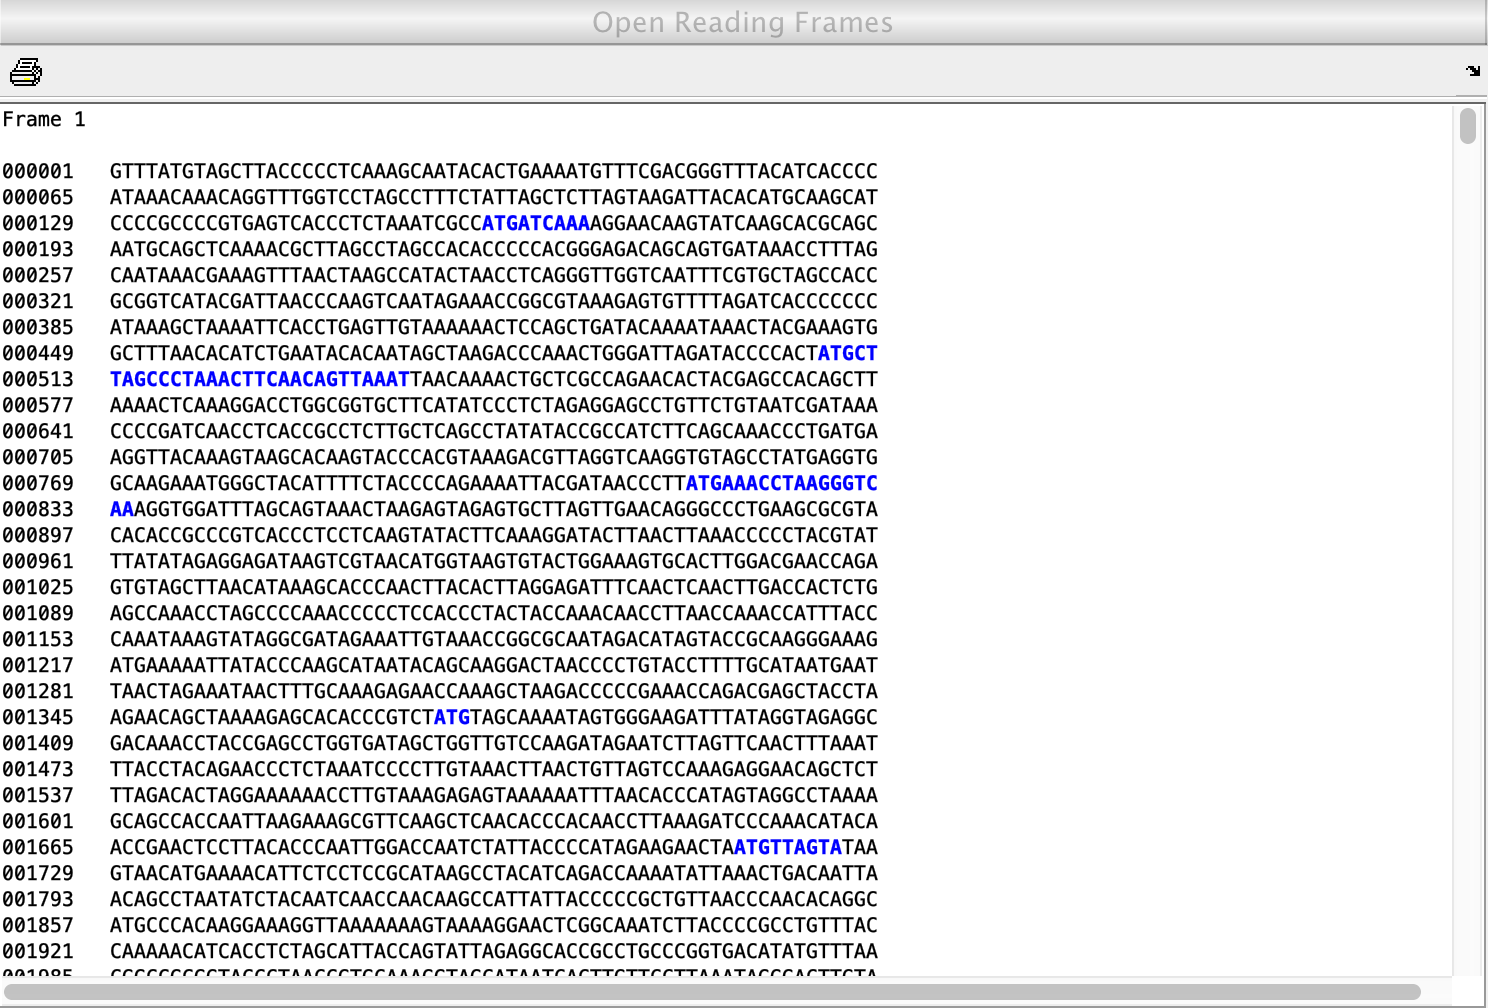

orf = seqshoworfs(chimp,'MINIMUMLENGTH',1, 'geneticcode',2,'frames','all');

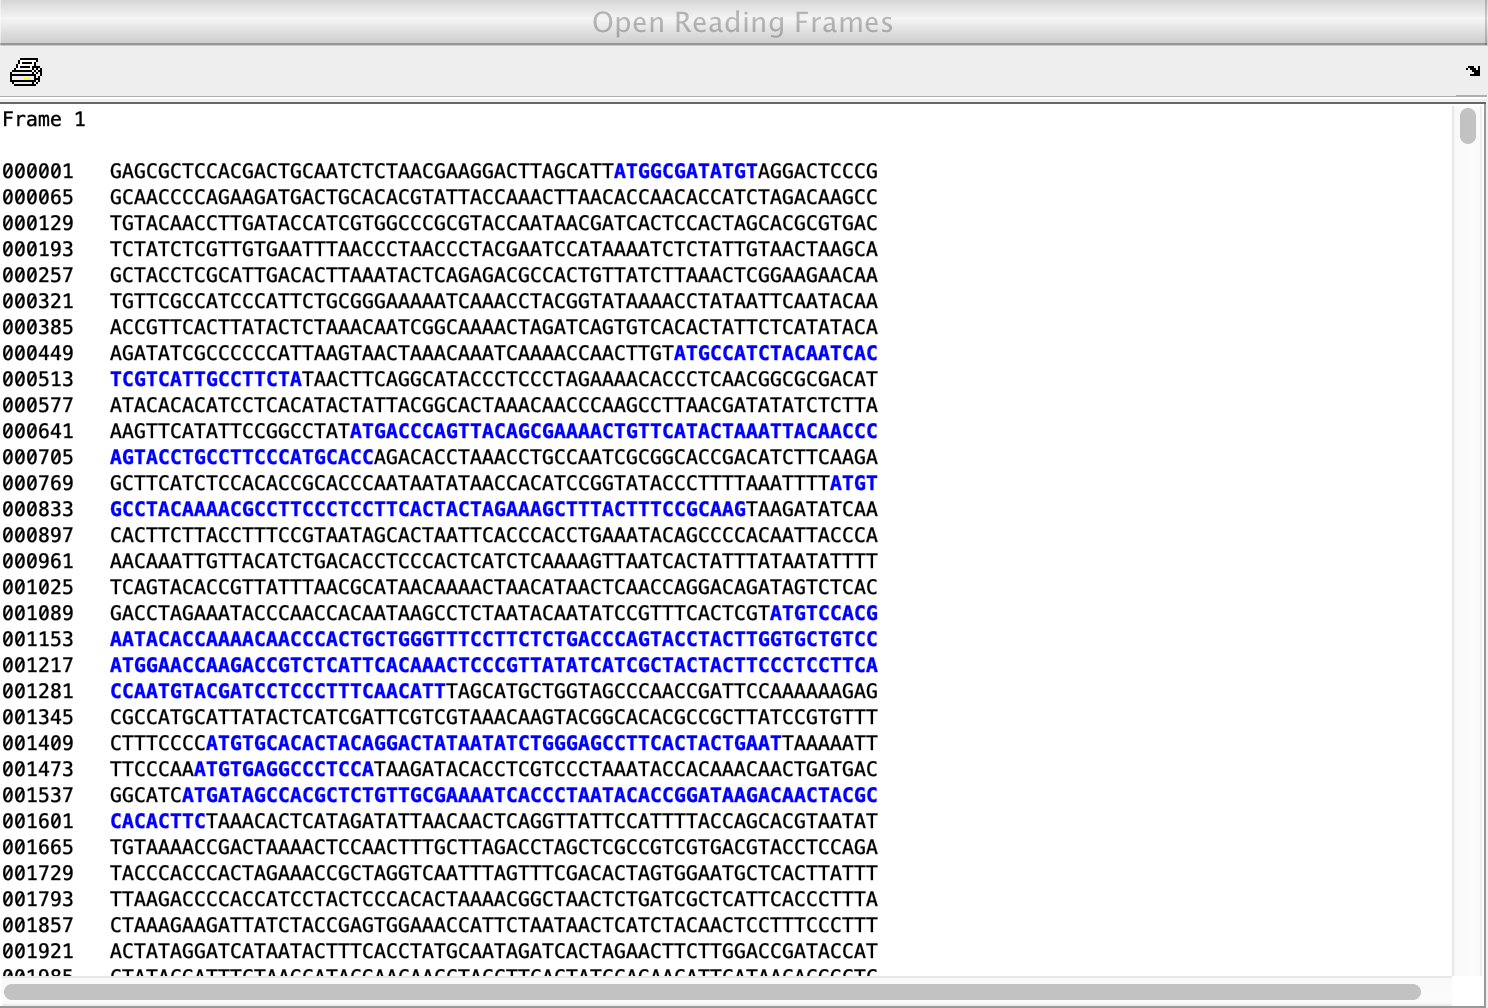

orf1=seqshoworfs(chimp(randperm(length(chimp))),'MINIMUMLENGTH',1,'geneticcode',2,'frames','all');

ORFLength=[];
for i=1:6
   for j=1:length(orf(i).Stop)
    ORFLength=[ORFLength; orf(i).Stop(j)+2 - orf(i).Start(j)];
   end
end
length(ORFLength)

ans = 432

ORFLength1=[];
for i=1:6
   for j=1:length(orf1(i).Stop)
    ORFLength1=[ORFLength1; orf1(i).Stop(j)+2 - orf1(i).Start(j)];
   end
end
length(ORFLength1)

ans = 443

max_threshold=max(ORFLength1)

max_threshold = 230

n_max=length(find(ORFLength>=max_threshold))

n_max = 12

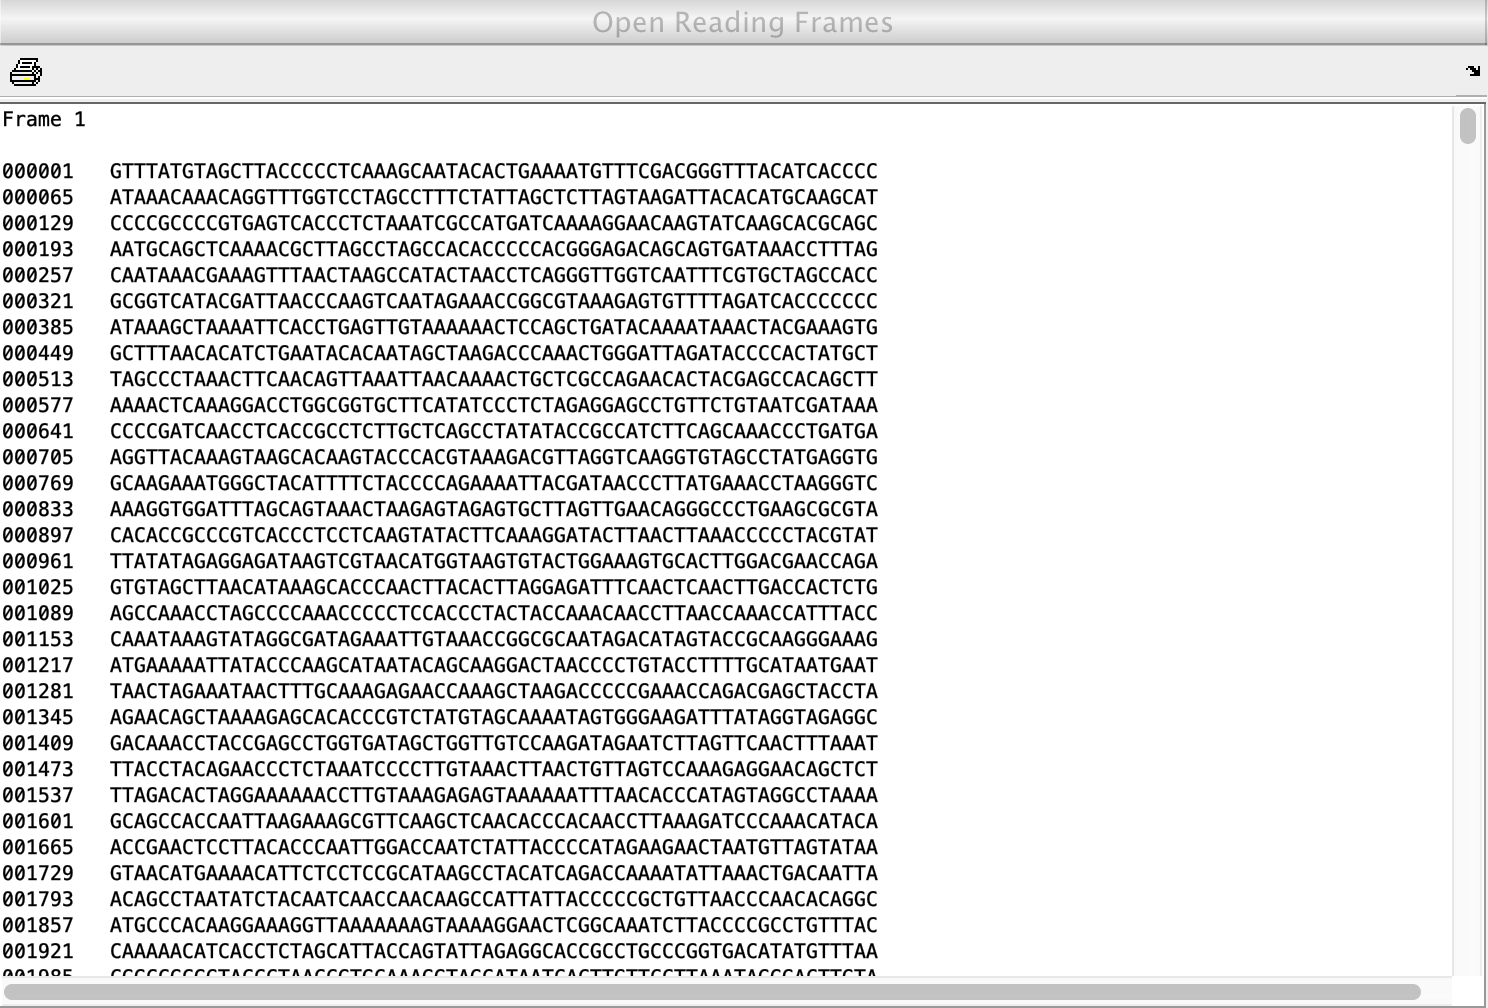

orf_threshold = seqshoworfs(chimp,'MINIMUMLENGTH',max_threshold/3, 'geneticcode',2,'frames','all');

orfNew=[];
for i=1:6
    for j=1:length(orf_threshold(i).Stop)
        orfNew=[orfNew; orf_threshold(i).Stop(j)+2 - orf_threshold(i).Start(j)];
    end
end
length(orfNew)

ans = 12

protein = chimp(orf_threshold(1).Start(1):orf_threshold(1).Stop(1)+2)

protein = 'ATGACCAACCTCCTACTCCTCATTGTACCCATCCTAATCGCAATAGCATTCCTAATGCTAACCGAACGAAAAATTCTAGGCTACATACAACTACGCAAAGGTCCCAACATTGTAGGTCCTTACGGGCTATTACAGCCCTTCGCTGACGCCATAAAACTCTTCACTAAAGAACCCTTAAAACCCTCCACTTCAACCATTACCCTCTACATCACCGCCCCAACCCTAGCCCTCACCATTGCCCTCTTACTATGAACCCCCCTCCCCATACCCAACCCCCTAGTCAATCTTAACTTAGGCCTCCTATTTATTCTAGCCACCTCCAGCCTAGCCGTTTACTCAATCCTCTGATCAGGGTGAGCATCAAACTCGAACTACGCCTTAATCGGTGCACTACGAGCAGTAGCCCAAACAATCTCATACGAAGTCACTCTAGCCATTATCCTACTGTCAACGCTACTAATAAGTGGCTCCTTCAATCTCTCTACCCTTGTCACAACACAAGAGCACCTCTGACTAATCCTGCCAACATGACCCCTGGCCATAATATGATTTATCTCTACACTAGCAGAGACCAACCGAACTCCCTTCGACCTTACTGAAGGAGAATCTGAACTAGTCTCAGGCTTTAATATCGAGTATGCCGCAGGCCCCTTTGCCCTATTTTTCATAGCCGAATACATAAACATTATTATAATAAACACCCTCACTGCTACAATCTTCCTAGGAGCAACATACAATACTCACTCCCCTGAACTCTACACGACATATTTTGTCACCAAAGCTCTACTTCTAACCTCCCTGTTCCTATGAATTCGAACAGCATATCCCCGATTTCGCTACGACCAGCTCATACACCTCCTATGAAAAAACTTCCTACCACTCACCCTAGCATCACTCATGTGATATATCTCCATACCCACTACAATCTCCAGCATCCCCCCTCAAACCTAA'

length(protein)/3

ans = 317

(61/64) ^ 315

ans = 2.7052e-07

aminoacid = nt2aa(protein, 'geneticcode',2)

aminoacid = 'MTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLVTTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGATYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT*'

aminoacid(1:50)

ans = 'MTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADA'

% seq1 = {Q9T9W3.2, AIV00479.1, AEQ36262.1, ANQ92411.1,AMB65312.1,
% AJO25286.1}
seq1 = getgenpept('Q9T9W3','SequenceOnly',true);
seq2 = getgenpept('AIV00479','SequenceOnly',true);
seq3 = getgenpept('AEQ36262','SequenceOnly',true);
seq4 = getgenpept('ANQ92411','SequenceOnly',true);
seq5 = getgenpept('AMB65312','SequenceOnly',true);
seq6 = getgenpept('AJO25286','SequenceOnly',true);
seqs = {seq1, seq2, seq3, seq4, seq5, seq6};
multialign(seqs)

ans = 6×318 char array
    'MPMTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLVTTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGATYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
    '--MTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLVTTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
    'TPMTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLITTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
  

% 'MPMTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLVTTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGATYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
%     '--MTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLVTTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
%     'TPMTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLITTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
%     '--MTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLITTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
%     '--MTNLLLLIVPVLIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLITTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTTYPRFRYDQLMHLLWKNFLPLTLASLMWYISMPTTISSIPPQT'
%     '--MTNLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNIVGPYGLLQPFADAMKLFTKEPLKPSTSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTLLMSGSFNLSTLITTQEHLWLILPTWPLAMMWFISTLAETNRTPFDLTEGESELVSGFNIEYAAGPFALFFMAEYMNIIMMNTLTATIFLGTTYNTHSPELYTTYFVTKALLLTSLFLWIRTAYPRFRYDQLMHLLWKNFLPLTLASLMWYISTPTTISSIPPQT'

humanProtein = getgenpept('AFF91323','SequenceOnly',true);
chimpProtein = aminoacid;

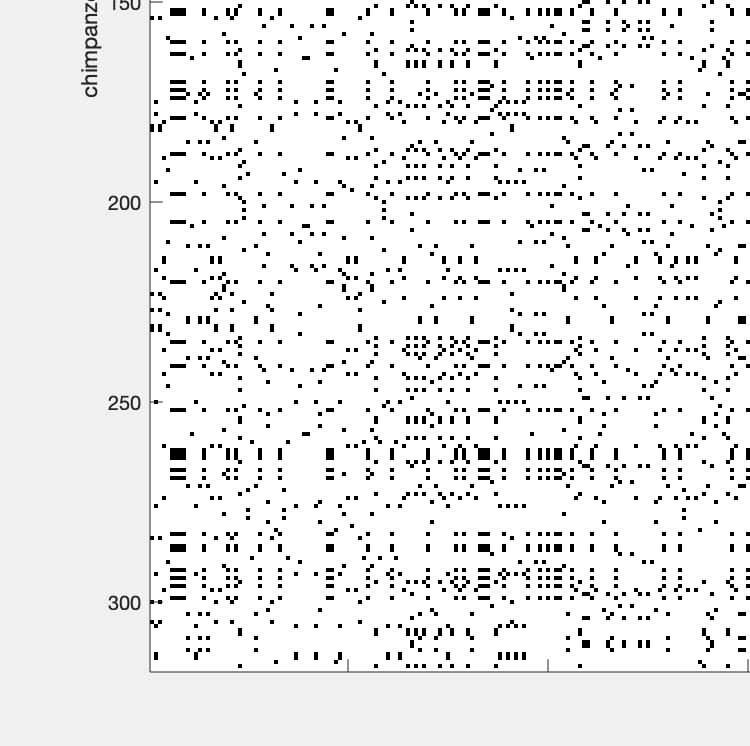

seqdotplot(humanProtein,chimpProtein)
xlabel('human');ylabel('chimpanzee');

[sc50,globAlig50] = nwalign(humanProtein,chimpProtein);
fprintf('Score = %g \n',sc50)

Score = 640 


[sc30,globAlig30] = nwalign(humanProtein,chimpProtein,'scoringmatrix','blosum30');
fprintf('Score = %g \n',sc30)

Score = 393.6 


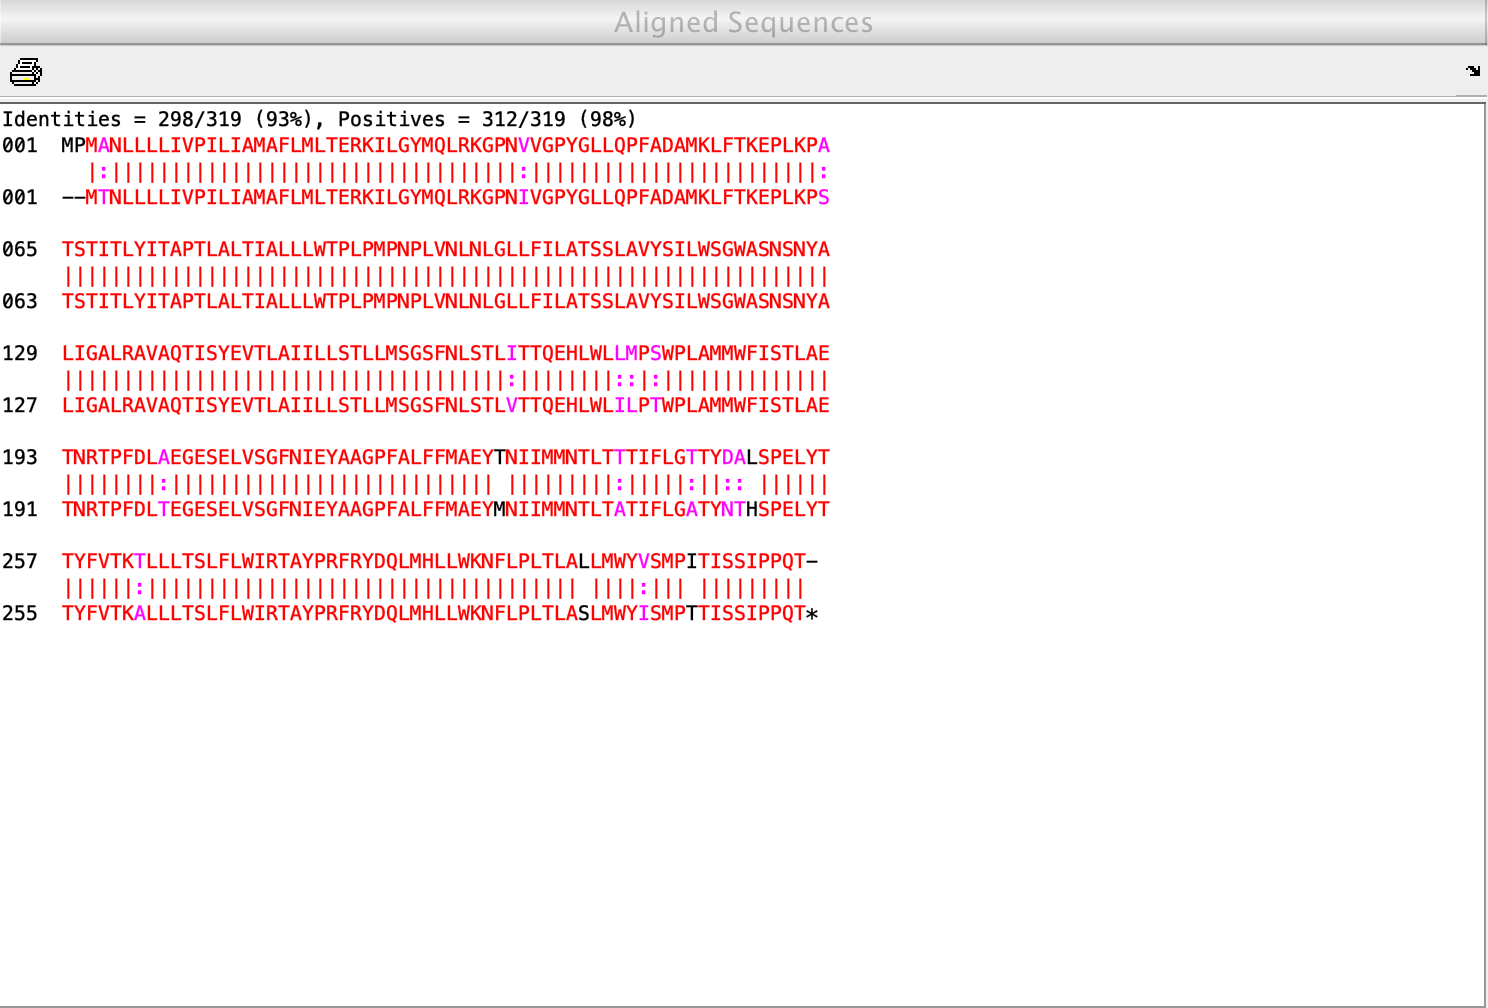

showalignment(globAlig50);


humanmt = getgenbank('NC_012920','SequenceOnly',true);


[score, globalAlignment] = swalign(humanmt,chimp,'scoringmatrix','blosum30');

score = 34867

globalAlignment = 3×17145 char array
    'GATCACAGGTCTATCACCCTATTAACCACTCACGGGAGCTCTCCATGCATTTGGTATTTTCGTCTGGGGGGTATGCACGCGATAGCATTGCGAGACGCTGGAGCCGGAGCACCCTATGTCGCAGTATCTGTCTTTGATTCCTGCCTCATCCTATTATTTATCGCACCTACGTTCAATATTACAGGCGAACATACTTACTAAAGTGTGTTAATTAATTAATGCTTGTAGGACATAATAATAACAATTGAATGTCTGCACAGCCACTTTCCACACAGACATCATAACAAAAAATTTCCACCAAACCCCCCCTCCCCCGCTTCTGGCCACAGCACTTAAACACATCTCTGCCAAACCCCAAAAACAAAGAACCCTAACACCAGCCTAACCAGATTTCAAATTTTATCTTTTGGCGGTATGCACTTTTAACAGTCACCCCCCAACTAACACATTATTTTCCCCTCCCACTCCCATACTACTAATCTCATCAATACAACCCCCGCCCATCCTACCCAGCACACACACACCGCTGCTAACCCCATACCCCGAACCAACCAAACCCCAAAGACACCCCCCACAGTTTATGTAGCTTACCTCCTCAAAGCAATACACTGAAAATGTTTAGACGGGCTCACATCACCCCATAAACAAATAGGTTTGGTCCTAGCCTTTCTATTAGCTCTTAGTAAGATTACACATGCAAGCATCCCCGTTCCAGTGAGTTCACCCTCTAAATCACCACGATCAAAAGGAACAAGCATCAAGCACGCAGCAATGCAGCTCAAAACGCTTAGCCTAGCCACACCCCCACGGGAAACAGCAGTGATTAACCTTTAGCAATAAACGAAAGTTTAACTAAGCTATACTAACCCCAGGGTTGGTCAATTTCGTGCCAGCCACCGCGGTCACACGATTAACCCAAGTCAATAGAAGCCGGCGTAAAGAGTGTTTTAGATCACCC

seqdotplot(humanmt,chimp)